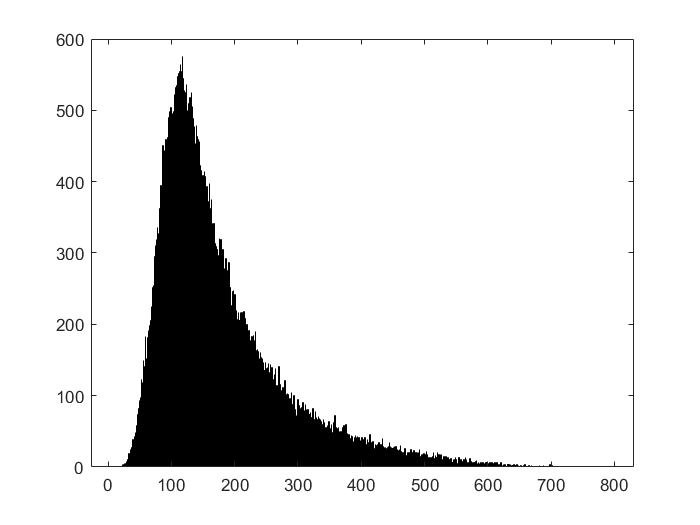

% Lab 7 - Kyle McEleney

signal = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
background = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

% 1

b_mass = background(4,:);
s_mass = signal(4,:);
total_mass = [b_mass, s_mass];

% Histogram of background mass measurement distribution
histogram(b_mass, 1000)

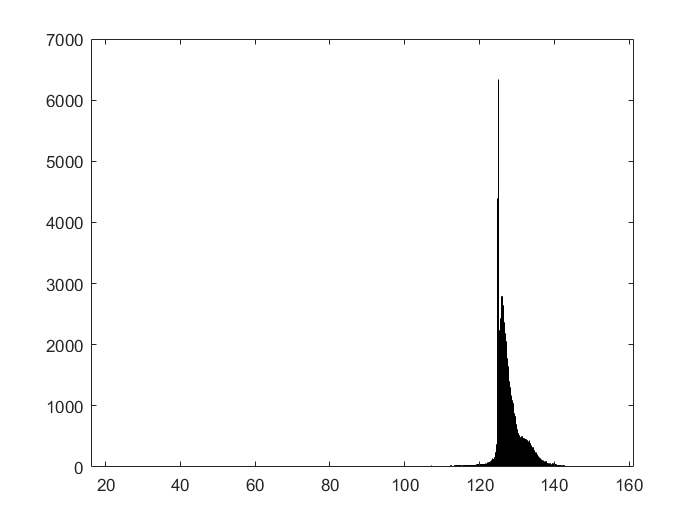

% Histogram of signal mass measurement distribution
histogram(s_mass, 1000)

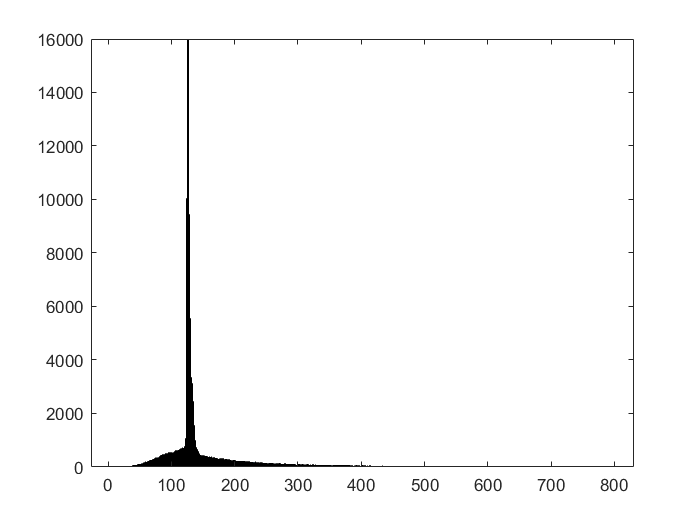


% Histogram of total mass distribution for combined dataset.
histogram(total_mass, 1000)

% Poisson statistics for significance calculation
poisson_pdf = makedist("Poisson", 'lambda', 2000);


% Expected significance without event selection for high transverse
% momentum data set using provided expected yields

% Expected yield of Higgs (signal) data set

N_higgs = 50;

% Expected yield of QCD (background) data set

N_QCD = 2000;

% Sigma value associated with the combined expected yield for the two data
% sets when compared to the pdf generated using the background set's lambda
% value (expected yield). 

significance = norminv(cdf(poisson_pdf, N_higgs+N_QCD))

significance = 1.1282

N_higgs/sqrt(N_QCD)

ans = 1.1180

% These two values are approximately similar. Since the square root of the
% lambda of a poisson distribution is equal to the standard deviation of
% the set for sufficiently large sets (which they are). 

% This may suggest that the ratio of the mean to the approximated standard deviation for the
% background acts as an approximation for the significance of the sum of
% the expected outcomes. 

% This ratio is also the inverse of the coefficient of variation which
% shows the extent of variability in relation to the mean. In this case,
% the inverse represents the significance of the the mean relative to the
% standard deviation, with higher values indicating a more reliable mean
% value (std goes down, effective mean value goes up).

% 2

% In order to optimize the expected significance, obviously insignificant
% data should be removed from the data set. Doing so will reduce the
% standard deviation significantly.

% The majority of the signal data set falls between 125 and 135 (grams?). 

% Extract data in the desireable range :

First_cut_b_mass = [];

for i = 1:length(b_mass)
    if (b_mass(1,i) < 150 & b_mass(1,i) > 120)
        First_cut_b_mass = [First_cut_b_mass, b_mass(1,i)];
    end
end

N_QCD_Mass = N_QCD * (length(First_cut_b_mass)/100000)

N_QCD_Mass = 358.7200

First_cut_s_mass = [];

for i = 1:length(s_mass)
    if (s_mass(1,i) < 150 & s_mass(1,i) > 120)
        First_cut_s_mass = [First_cut_s_mass, s_mass(1,i)];
    end
end

N_Higgs_Mass = N_higgs * (length(First_cut_s_mass)/100000)

N_Higgs_Mass = 47.9640

% Significance of the sum of the two data set Ns:
N_Higgs_Mass/sqrt(N_QCD_Mass)

ans = 2.5324

% Using this process, the set of mass cuts which will yield the highest
% significance will be the range that maximizes the number of signal datum
% and minimizes the number of the background. This could be done with a
% nested for loop which sweeps through several combinations of min/max
% discrimination values (probably just integer values) and logs the resultant significance.

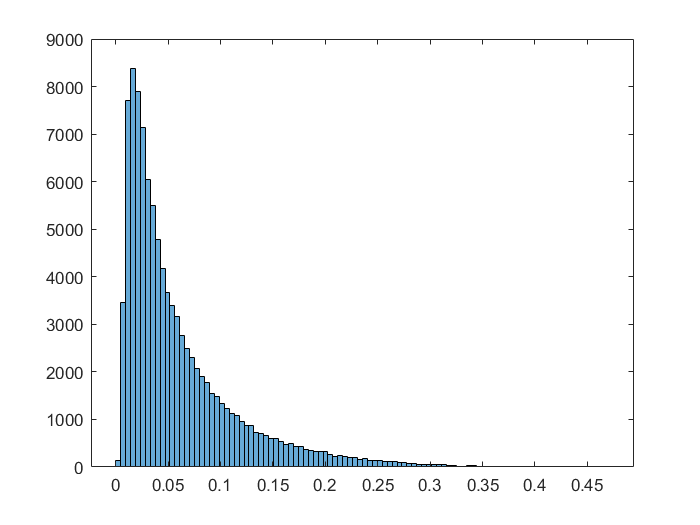


% 3 
% By looking through the plots generated in lab 5 and the analysis found
% there, it seems as though the ECF2 data set would be ideal for maximizing
% significance. This is due to the majority of the data being skewed in
% opposite directions relative to the entire data set. There are
% effectively two peaks which are to be exploited to max/min yields.


% Extract data from data sets
b_e2 = background(5,:);
s_e2 = signal(5, :);
e2_stacked = [b_e2, s_e2];

% Histogram of background data
histogram(b_e2, 100)

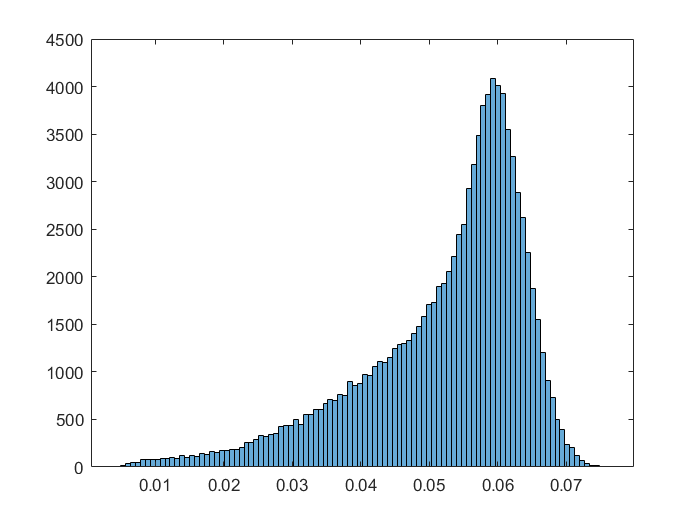


% Histogram of signal data
histogram(s_e2, 100)

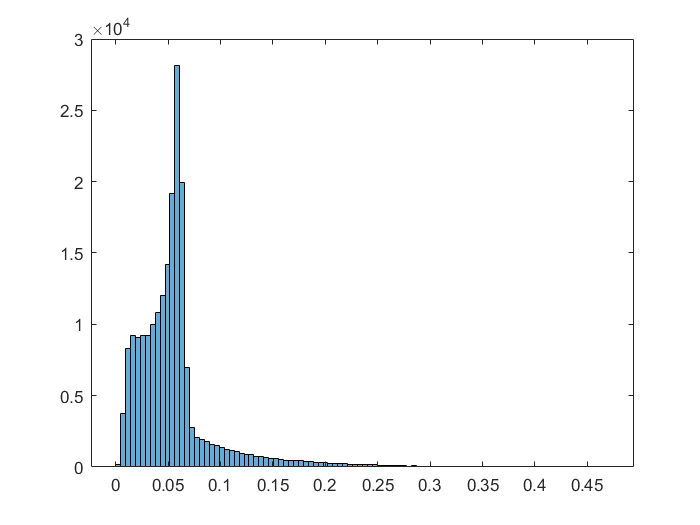

% Histogram of stacked data
histogram(e2_stacked, 100)

% This suggests that the desired range is something like 0.055-0.065

First_cut_b_e2 = [];

for i = 1:length(b_e2)
    if (b_e2(1,i) < 0.065 & b_e2(1,i) > 0.05)
        First_cut_b_e2 = [First_cut_b_e2, b_e2(1,i)];
    end
end

N_QCD_e2 = N_QCD * (length(First_cut_b_e2)/100000);
First_cut_s_e2 = [];

for i = 1:length(s_e2)
    if (s_e2(1,i) < 0.065 & s_e2(1,i) > 0.05)
        First_cut_s_e2 = [First_cut_s_e2, s_e2(1,i)];
    end
end

N_Higgs_e2 = N_higgs * (length(First_cut_s_e2)/100000)

N_Higgs_e2 = 30.0850

% Significance of the sum of the two data set Ns:
N_Higgs_e2/sqrt(N_QCD_e2)

ans = 2.1129

% While this significance is promising, additional passes may need to be
% taken with varied parameters in order to increase the significance to a
% level comparable to the mass. This is mostly due to the fact that the
% mass has such a high concentration of signal values that discrimination
% is far more effective for a small range since the disparity of data
% within the range is accentuated.


% 4 

% It seems that both my lab partner and I selected the same data set for
% discrimination, however my range of 0.05 to 0.065 fared better than his
% of .1-.2 for our respective data sets. Mine yielded a significance of
% 2.11 while his yielded 1.09.